# Main code to run

Schematic of a rod segment defining all the quantities

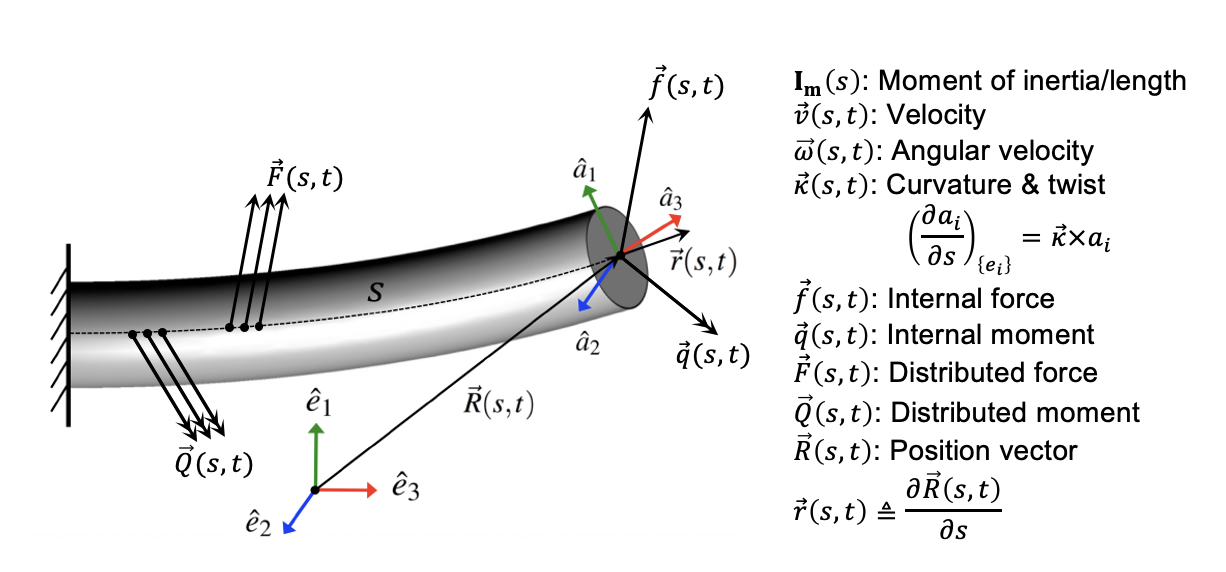

clear all; clc;

%% Numerical parameters
at = 0.5; bt = 0.5; gt = 0.5; as = 0.5; bs = 0.5; gs =0.5;  
%at = 0.3889; bt = 0.4444; gt = 0.5556; as = 0.5; bs = 0.5; gs =0.5; 
%% 
dt = 0.001;    % time-step 
nT = 2000;      % Number of  time-steps
Length = 1;       % has to be defined in 'YG_new_direct' as well
ds = 0.01; % has to be defined in 'F_vec' and 'YG_new_direct' and 'jacobina_Fy' and 'Yprime'
N = Length/ds +1; % Number of  space-steps

%% Global variables

global E I1 I2 I3 G ro Ac radi m poiss

poiss=0.25;

radi=0.0141/2;
I1=(pi/4)*(radi^4);
Ac=pi*radi^2;
m=9.8;
ro=m/Ac;
I2=I1;
I3=2*I1;

E=10000/I1;
G=E/(2*(1+poiss));
    
%Constants of taylor series expansion for a CL up to order 5
% Liniear C11, C21, C31 not 0

C10=0;
C11=E*I1;
C12=0;
C13=0;
C14=0;
C15=0;
C20=0;
C21=E*I2;
C22=0;
C23=0;
C24=0;
C25=0;
C30=0;
C31=G*I3;
C32=0;
C33=0;
C34=0;
C35=0;

%% Set up the iterations
basis = eye(12);

% initial curvature:
k0=[0; 0; 0];

Y0 = zeros(12,N); % initial Y at all node
for i=1:N
    Y0(7:9,i)=k0;
end
YG = Y0; % first Guess
YG_new = zeros(12,N); 
Ydot_initial = Ydot0(Y0,ds);
Y_time_march(:,:,1) = Y0;


%% time marching start here
for d = 1:nT
  Yprime_previous = Yprime(Ydot_initial,Y0,d);
  %% iteration start here
  e = 12;
  if mod(d,50) == 0
      d
  end
  while e>1e-9
    YG_previous = YG;
    co_basis = zeros(12,6,N);
    Ypar = zeros(12,N);
    
    %% Left hand BC @ s=0:
    YP1 = leftbound(YG_previous);

    for i = 1:6
            co_basis(:,i,1) = basis(:,i+6);
    end
    for i = 1:12
            Ypar(i,1) = YP1(i,1);
    end

    H2toN = zeros(12,N-1);
    A2toN = zeros(12,12,N-1);
    B2toN = zeros(12,12,N-1);

    for i = 1:N-1
        H2toN(:,i) = H_mat(Ydot_initial(:,i+1),Ydot_initial(:,i),...
            Yprime_previous(:,i+1),Yprime_previous(:,i),Y0(:,i+1),...
            Y0(:,i),YG(:,i),YG(:,i+1),as,at,bs,bt,gs,gt,ds,dt,i+1,d);
        A2toN(:,:,i) = A_mat(Y0(:,i+1),Y0(:,i),YG(:,i+1),YG(:,i),as,bs,at,bt,gs,gt,dt,ds,i+1); % 12x12 and 3rd dimension is node
        B2toN(:,:,i) = B_mat(Y0(:,i+1),Y0(:,i),YG(:,i+1),YG(:,i),as,bs,at,bt,gs,gt,dt,ds,i+1); % 12x12 and 3rd dimension is node
    end

    for j = 1:N-1
        for i = 1:6
            co_basis(:,i,j+1) = (A2toN(:,:,j))\(-B2toN(:,:,j)*co_basis(:,i,j));
        end      
    end
    %% solvin for particular solution   
    for j = 1:N-1     
            Ypar(:,j+1) = (A2toN(:,:,j))\((H2toN(:,j))-(B2toN(:,:,j)*Ypar(:,j)));
    end
    %%  Right hand BC @ s=L
    YG_prev=YG;
    YG = YG_new_direct(co_basis,Ypar,dt,d,YG_prev); 

    diff=norm(YG-YG_new);
    e = norm(YG-YG_previous);
    
  end
  Y_time_march(:,:,d+1) = YG; % v,w,k,f
  Ydot_initial = Ydot(Y_time_march(:,:,d+1),Y_time_march(:,:,d),Ydot_initial,gt,dt);
  Y0 = YG; % Y0 = Yold
end


%% Save the variables
save('variables_bending.mat')

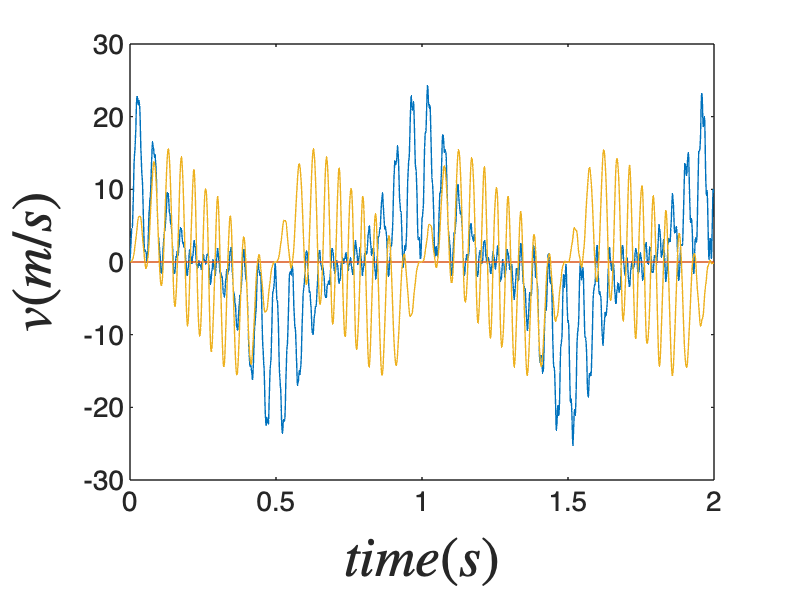

%% Post Processing

nT=length(Y_time_march(1,end,:))-1;
len=0:ds:Length;
time=0:dt:nT*dt;

%%Visualize each variable at the free end
set(0,'defaultTextInterpreter','latex')
plot(time,squeeze(Y_time_march(1,end,:)))
hold on
plot(time,squeeze(Y_time_march(2,end,:)))
plot(time,squeeze(Y_time_march(3,end,:)))
hold off
ylabel('$v(m/s)$','FontSize',20)
xlabel('$time(s)$','FontSize',20)

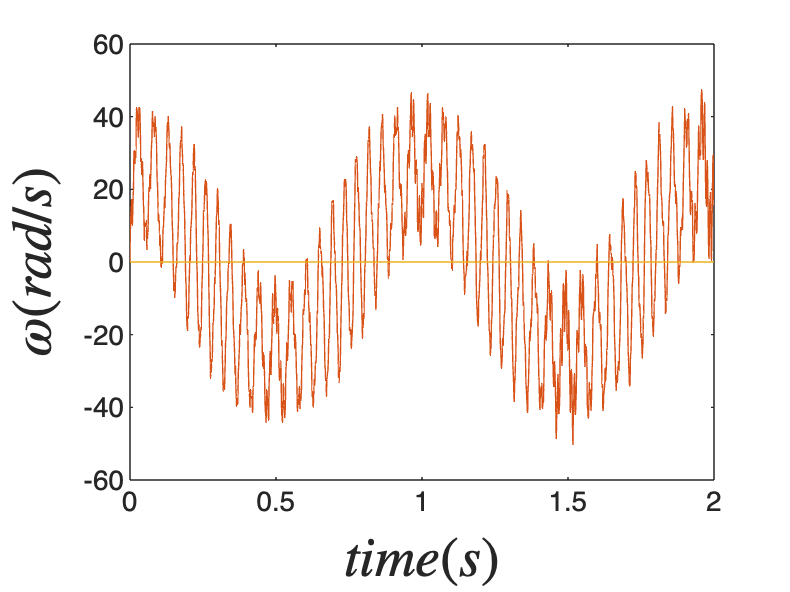

plot(time,squeeze(Y_time_march(4,end,:)))
hold on
plot(time,squeeze(Y_time_march(5,ceil(end),:)))
plot(time,squeeze(Y_time_march(6,end,:)))
hold off
ylabel('$\omega(rad/s)$','FontSize',20)
xlabel('$time(s)$','FontSize',20)

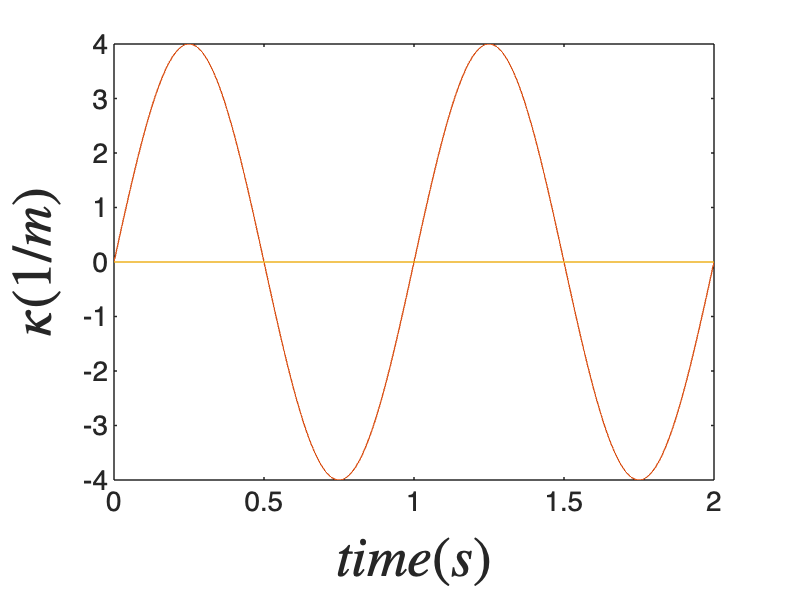

plot(time,squeeze(Y_time_march(7,end,:)))
hold on
plot(time,squeeze(Y_time_march(8,end,:)))
plot(time,squeeze(Y_time_march(9,end,:)))
hold off
ylabel('$\kappa(1/m)$','FontSize',20)
xlabel('$time(s)$','FontSize',20)

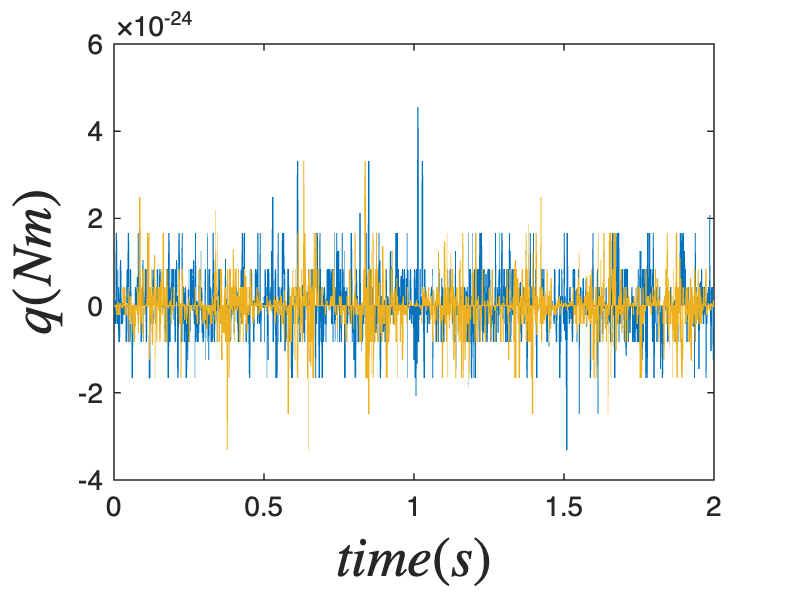

plot(time,squeeze(Y_time_march(10,end,:)))
hold on
plot(time,squeeze(Y_time_march(11,end,:)))
plot(time,squeeze(Y_time_march(12,end,:)))
hold off
ylabel('$q(Nm)$','FontSize',20)
xlabel('$time(s)$','FontSize',20)

%% Computing position using Kappa

for i=1:nT
    K_temp = Y_time_march(7:9,:,i);
    R = zeros(3,N);
    L = [1 0 0;0 1 0;0 0 1];

    for j=1:N-1
        theta_v = ds*((K_temp(:,j)+K_temp(:,j+1))/2);
        theta_m(1,2)= -theta_v(3,1);
        theta_m(1,3)=  theta_v(2,1);
        theta_m(2,1)=  theta_v(3,1);
        theta_m(2,3)= -theta_v(1,1);
        theta_m(3,1)= -theta_v(2,1);
        theta_m(3,2)=  theta_v(1,1);
        L_new = expm(-theta_m)*L;
        L = L_new;
        r = L(3,:)';
        R(:,j+1) = R(:,j) + r*ds;
    end
    x1(i,:) = R(1,:);
    x2(i,:) = R(2,:);
    x3(i,:) = R(3,:);
    
    %ix(i)=x1(i,end);
    %F(:,i) = L'*[Y_time_march(10,end,i); Y_time_march(11,end,i); Y_time_march(12,end,i)];
end


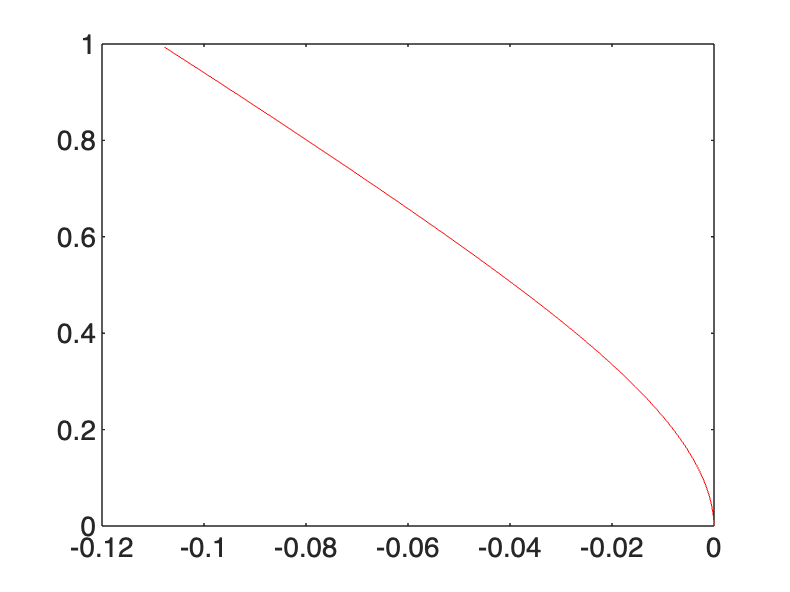

plot(x1(end,:),x3(end,:),'r','LineWidth',0.2)

set(0,'defaultTextInterpreter','latex')
v = VideoWriter('test_bending','MPEG-4');

The specified profile is not valid.

open(v);
for i=1:5:nT
    plot(x3(i,:),x1(i,:),'bla','LineWidth',2)
    set(gca,'FontSize',16);
    xlim([-0.5 1.5])
    ylim([-1 1])
    ylabel('$z$ (m)','FontSize',22)
    xlabel('$x$ (m) ','FontSize',22)
    frame=getframe(gcf);
    writeVideo(v,frame);
end
close(v);